## **Investment Replica**

close all
clear 
clc

load('InvestmentReplica.mat')

## Target index: HEDGE FUND

We choose as target index HFRXGL: Hedge Fund Research HFRX Global

y = price2ret(HFRXGL); 
target = ret2price(y);

We decided to add three different spreads: 

- Spreads between 2yrs and 10yrs germany gov bond

- Spreads between 2yrs and 10yrs US treasury 

- Spread between the Tech Equity and the US Equity

X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1) price2ret(RX1-DU1) price2ret(TY1-TU2) price2ret(NQ1-ES1)];

## Data analysis

We can see that the futures returns behave really differently and they're mostly uncorrelated. So this correlation plot will help in visualizing the relationships and strength of correlation between each regressor and the target variable

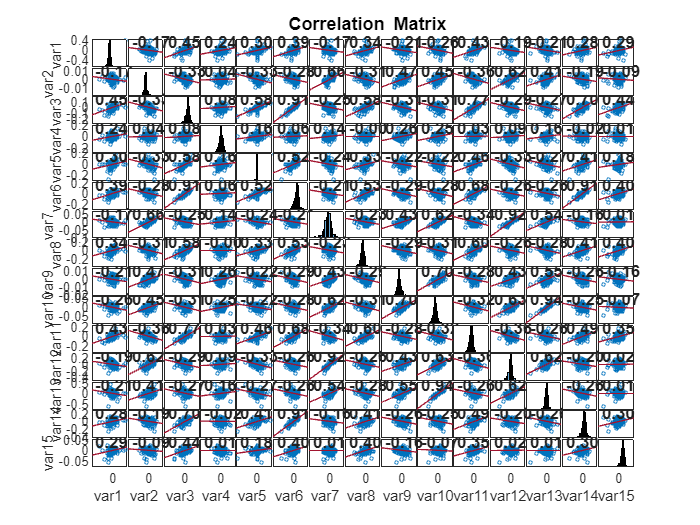

figure
corrplot([X,y])

Remove the variables with low correlation with the hedge fund index:

- DU1: 2y germany gov bond 

- GC1: gold

- RX1: 10y germany gov bond

- TY1: 10y US treasury

- german spread 10y-2y

- us spread 10y-2y

Now we can update the matrix X keeping only the regressors we want

X = [price2ret(CO1) price2ret(ES1) price2ret(NQ1) price2ret(TP1)...
           price2ret(TU2) price2ret(VG1) price2ret(NQ1-ES1)];


Let's show again correlation plot among all regressors and target variable

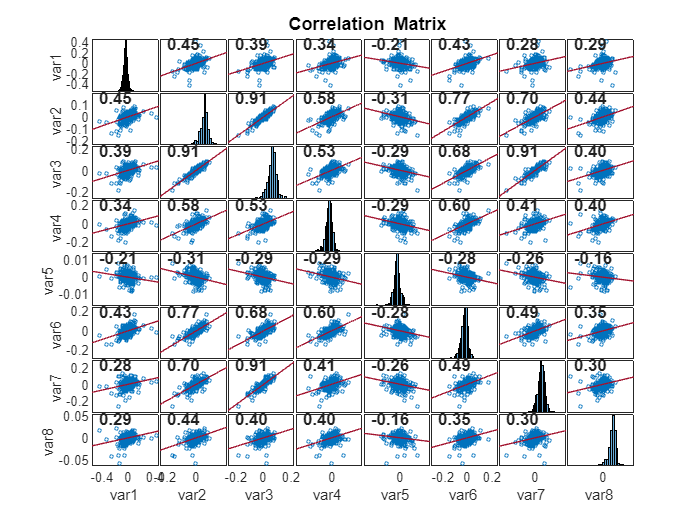

figure
corrplot([X,y])

Now all our assets are quite correlated with the target variable, here's the plot of their trends

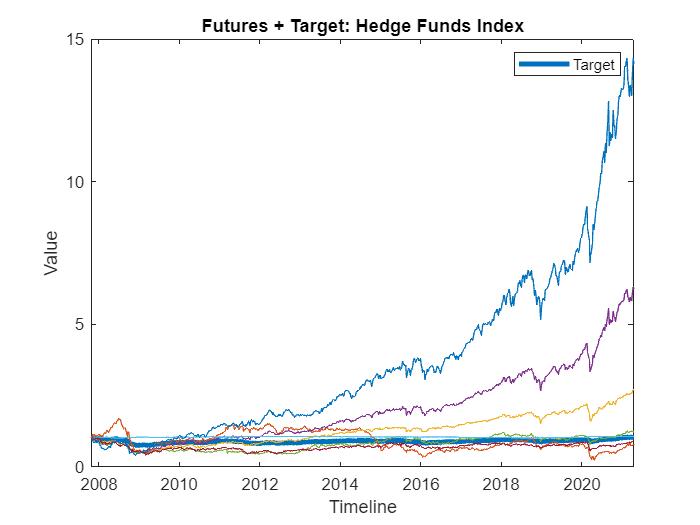

figure
plot(XTab.Date,target,'DisplayName','HFRX Index','LineWidth',3);
xlabel('Timeline')
ylabel('Value')
hold on
plot(XTab.Date, ret2price(X))
legend('Target')
title('Futures + Target: Hedge Funds Index')

## Max Leverage Threshold

We utilize Elastic Net regression for portfolio replica, combining the properties of Lasso and Ridge regression with a high Alpha value for Lasso-like behavior. We set a maximum leverage threshold to ensure the portfolio's gross exposure does not exceed 200% (keeping the sum of the absolute weights of the futures at 100% or less), and perform data normalization during preprocessing to standardize features and enhance the model's performance and stability.

Set lengths of the four possible rolling windows in weeks (8 = 2m, 52 = 1Y, 104 = 2Y, 156 = 3Y)

rollingWindow3y = 156;                                                    
rollingWindow2y = 104;
rollingWindow1y = 52;
rollingWindow2m = 8;
window_used = rollingWindow1y;

Selection of an high Alpha so that the Elastic Net tends to be closer to a Lasso regression which helps us reducing the number of futures in our portfolio

alpha = 0.85;                                                              

Initialize needed vectors

returns_lev1 = [];                           % (weekly) returns of our replica portfolio
grossExposure_lev1 = [];                     % (weekly) Gross Exposure of our portfolio
weights_lev1 = [];                           % (weekly) weights of our portfolio
endSample = 0;                               % index of the last element of the train-val rolling window

Where do we start our study?

1      -->  23-Oct-2007: first time point in the dataset

116  -->  05-Jan-2010: we don't want our training set to contain the biased data originated from the financial crysis

start_index = 116;
j = start_index; 

warning('off', 'all')

Cycle through the whole set, performing rolling evaluation

tic
while endSample <= (length(X) - 2)
    
    % Update the needed indexes
    startSample = j; % index of the first element of the rolling window
    endSample = j+window_used-1; 
    % the train-val rolling window is of window_used length

    % Select train-val dataset
    x_train = X(startSample:endSample,:);
    y_train = y(startSample:endSample);

    % Preprocessing of the data
    mean_X = mean(x_train,1);
    std_X = std(x_train,1);
    x_train = (x_train - mean_X)./std_X;

    % x_train = (x_train - min(x_train,[],1))./(max(x_train,[],1) - min(x_train,[],1));

    mean_y = mean(y_train);
    std_y = std(y_train);
    y_train = (y_train - mean_y)./std_y;

    % y_train = (y_train - min(y_train))/(max(y_train) - min(y_train));

    % Elastic Net regression to estimate weights of the replica, for the
    % current moving window; there's 5-fold cross validation

    [weights_mat,fitinfo] = lasso(x_train,y_train,'Alpha',alpha,'CV',5, ...
        'Intercept',false,'NumLambda',150,'LambdaRatio',1e-3,'UseCovariance',true);
     
    % weights_mat is a matrix, that has a column of regressor weights, each
    % corresponding to a particular regularization coefficent lambda; while
    % fitinfo is a struct containing useful information about the
    % regression performed, including: index1SE and indexMinMSE which give
    % us the indexes such that we have, respectively, the lamnbda with
    % minimum MSE or largest lambda within 1 std.dev. of the min MSE

    % Take index of the lambda
    % lam_idx = round((fitinfo.Index1SE + fitinfo.IndexMinMSE)/2); 
    lam_idx = fitinfo.IndexMinMSE;

    % Select the current weights corresponding to this lambda
    weights_curr = weights_mat(:,lam_idx);

    % Check the 200% leverage threshold (which corresponds to sum of the
    % weights smaller or equal than 1)
    while (sum(abs(weights_curr))>1) % while threshold not satisfied

        % Select different weights moving to a bigger lambda
        lam_idx = lam_idx+1;
        weights_curr = weights_mat(:,lam_idx);

    end

    % Add all the values to the final vectors
    grossExposure_lev1 = [grossExposure_lev1; sum(abs(weights_curr))];
    weights_lev1 = [weights_lev1; weights_curr'];

    % Normalize also the test set
    % x_test = (X(endSample + 1,:) - min(x_train,[],1))./(max(x_train,[],1) - min(x_train,[],1));
    x_test = (X(endSample + 1,:) - mean_X)./std_X;

    % Find the normalized returns, and then de-normalize them
    returns_curr = x_test*weights_curr;
    % returns_curr = returns_curr*(max(y_train) - min(y_train)) + min(y_train);
    returns_curr = returns_curr*std_y + mean_y;

    % Add them to the clone returns vector
    returns_lev1 = [returns_lev1; returns_curr];

    % Update counter j
    j = j+1;
 end

toc

Elapsed time is 40.446774 seconds.


warning('on', 'all')

## Plots

Plot of the total gross exposure of our replica portfolio

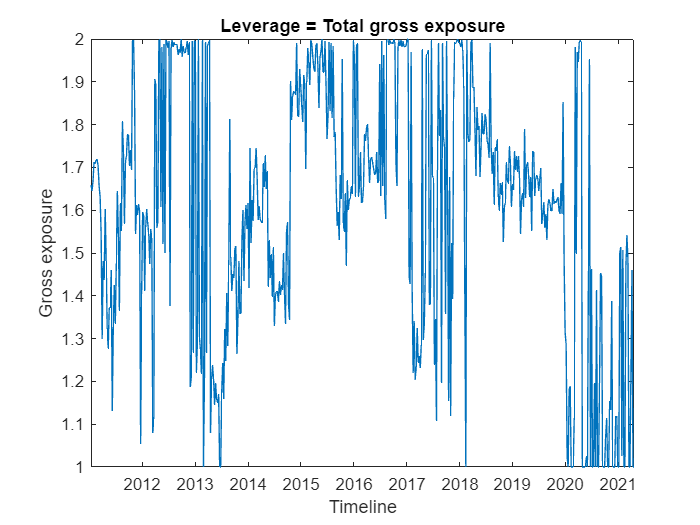

figure
plot(Date(start_index+window_used+1:end),grossExposure_lev1+1); % add 1 for your collateral + margins
title('Leverage = Total gross exposure')
xlabel('Timeline')
ylabel('Gross exposure')
hold off; 

Plot of the evolution in time of the weights of our replica portfolio

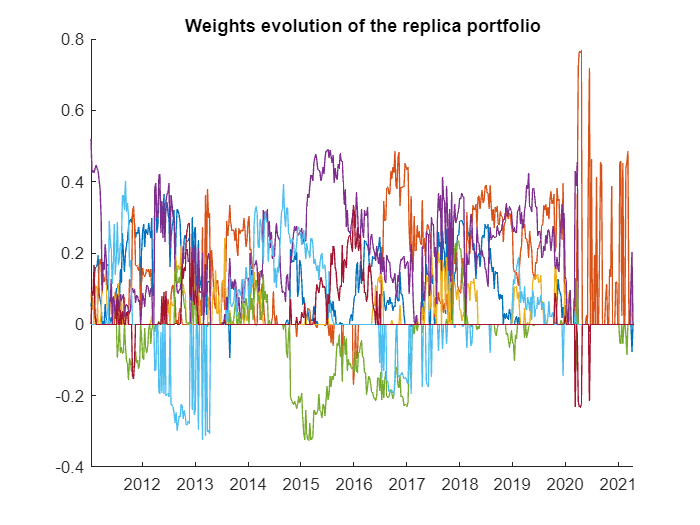

figure
hold on
for i = 1:size(weights_lev1,2)
    plot(Date(start_index+window_used+1:end),weights_lev1(:,i))
end
title('Weights evolution of the replica portfolio')

Barplot of the average weight of the assets during the whole timespan

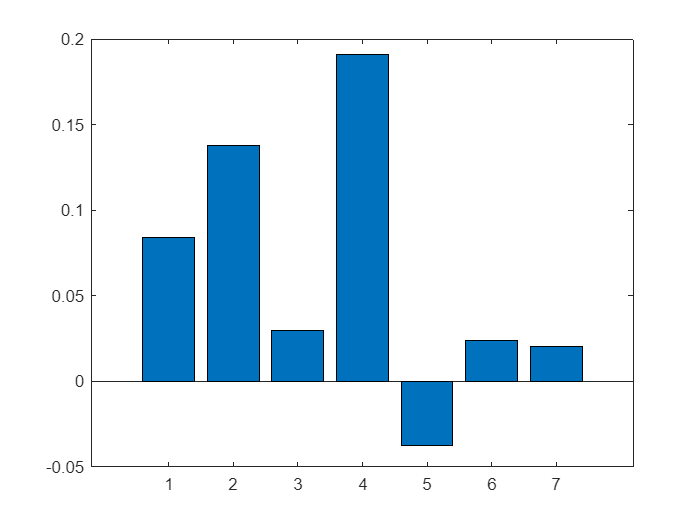

mean_weights = mean(weights_lev1,1);
figure
bar(mean_weights)

Evolution of the Weights Year by Year for Replica Portfolio

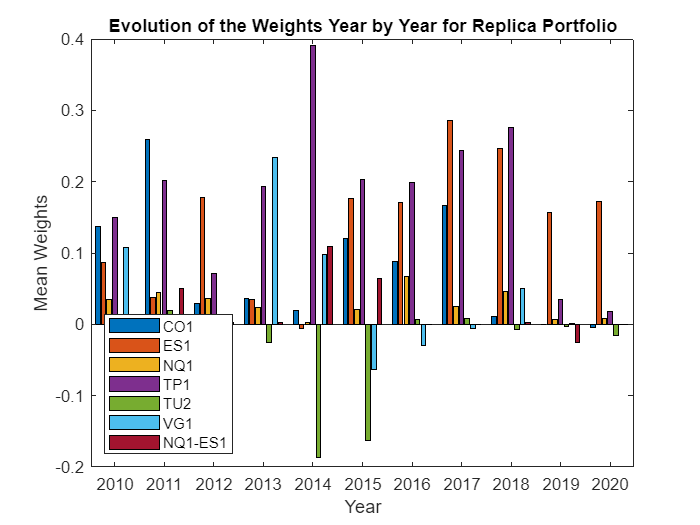

% Evaluate number of full years in our timespan
amount_years = floor(size(weights_lev1,1)/52);
mean_weights_yearly = []; % prepare vector

for i = 1:amount_years
    % save the mean annual weights for each asset, year by year
    mean_weights_yearly(:,i) = mean(weights_lev1((i-1)*52+1:i*52,:),1);
end
% Save the mean annual weights for the final dates
mean_weights_yearly(:,i+1) = mean(weights_lev1(i*52+1:end,:),1);

% Prepare variables needed for the barplots
years = 2010:(2010 + amount_years);
asset_labels = {'CO1', 'ES1', 'NQ1', 'TP1', 'TU2', 'VG1', 'NQ1-ES1'};

figure
bar(mean_weights_yearly')
title('Evolution of the Weights Year by Year for Replica Portfolio')
xlabel('Year')
ylabel('Mean Weights')
xticks(1:length(years))  % set the ticks on the x-axis
xticklabels(years)       % set the labels of the x-axis
legend(asset_labels, 'Location', 'SouthWest')

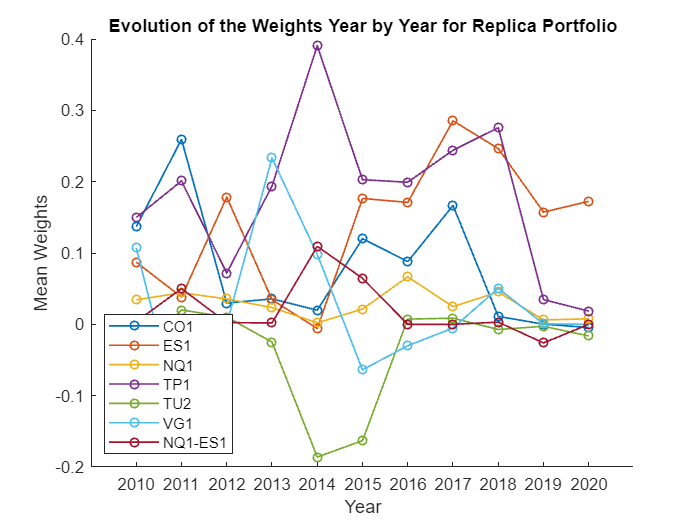

figure
hold on
for asset_idx = 1:size(mean_weights_yearly, 1)
    xx = 1:length(years);
    yy = mean_weights_yearly(asset_idx, :);
    plot(xx, yy, '-o', 'LineWidth', 1, 'MarkerSize', 5);
end
title('Evolution of the Weights Year by Year for Replica Portfolio')
xlabel('Year')
ylabel('Mean Weights')
xticks(1:length(years))  % set the ticks on the x-axis
xticklabels(years)       % set the labels of the x-axis
legend(asset_labels, 'Location', 'SouthWest')

Plot results of our investment replica model

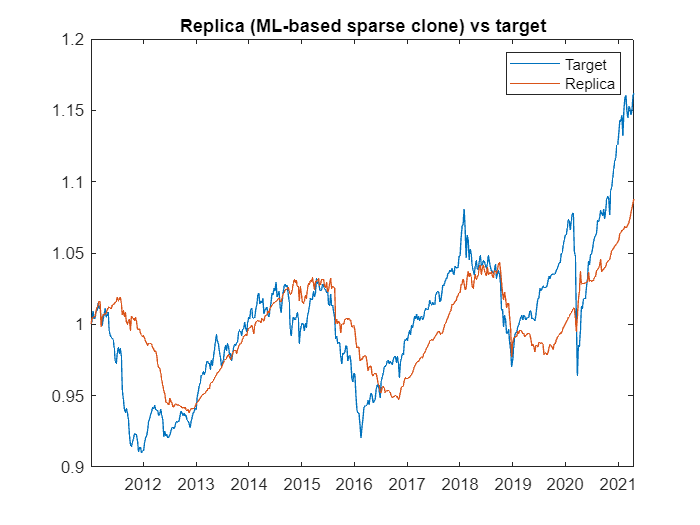

figure
plot(Date(start_index+window_used:end),ret2price(y(start_index+window_used:end)),'DisplayName','Target');
hold on;
plot(Date(start_index+window_used:end),ret2price(returns_lev1),'DisplayName','Replica');
legend
title('Replica (ML-based sparse clone) vs target')
hold off;

## Evaluate our model: Metrics

Compute Mean Squared Error (MSE) and Mean Absolute Error (MAE)

mse_lev1 = mean((ret2price(returns_lev1) - ret2price(y(start_index+window_used:end))).^2)

mse_lev1 = 0.0011

mae_lev1 = mean(abs(ret2price(returns_lev1) - ret2price(y(start_index+window_used:end))))

mae_lev1 = 0.0251

Tracking Error Volatility

TE_1 = returns_lev1 - y(start_index+window_used: end); 
TEV_1 = std(TE_1)*sqrt(52)  % annualized

TEV_1 = 0.0407

Log-returns of the clone and the target

logRClone_1 = diff(log(ret2price(returns_lev1)));
logRTarget_1 = diff(log(ret2price(y(start_index+window_used: end))));

logTE_1 =  logRClone_1 - logRTarget_1;  % log-returns tracking error

Mean yearly total returns of target and clone

meanTRTarget_1 = exp(mean(logRTarget_1)*52) - 1

meanTRTarget_1 = 0.0147

meanTRClone_1 = exp(mean(logRClone_1)*52) - 1

meanTRClone_1 = 0.0082

Mean excess return of the clone over the target

meanER_1 = exp(mean(logTE_1)*52) - 1

meanER_1 = -0.0064

Information Ratio: mean excess return over the tracking error volatility - similar idea to Sharpe Ratio

IR_1 = meanER_1/TEV_1

IR_1 = -0.1565

Weekly turnovers of each asset in our portfolio 

[Turnover_1] = our_calcTurnover(weights_lev1);

Mean annual turnover (since we're computing every metric as annual)

meanTurnover_1 = sum(mean(Turnover_1)*52)

meanTurnover_1 = 10.6130

Mean trading costs (percentage)

tradingCosts = 4e-4;      % transaction costs (hp: buyCosts=sellCost) 4 bps
meanTradingCosts_1 = meanTurnover_1*tradingCosts

meanTradingCosts_1 = 0.0042

Net Total returns of the clone - accounting for transactions costs

NetTR_1 = meanTRClone_1 - meanTradingCosts_1 

NetTR_1 = 0.0040

Net Excess returns of the clone - accounting for transactions costs

NetER_1 = meanER_1 - meanTradingCosts_1 

NetER_1 = -0.0106

Net Information Ratio - accounting for transactions costs

NetIR_1 = NetER_1/TEV_1

NetIR_1 = -0.2607

## Max Leverage Threshold - Trading costs

Now we aim to explore the same process as described above, with the added consideration of trading costs incurred due to frequent rebalancing. This code implements two constraints to minimize trading costs: the first restricts small trades by avoiding buying/selling for futures with minimal variations, while the second condition prevents changes in weights if the Hedge Fund Index shows little movement, thus balancing the tradeoff between trading expenses and tracking capacity.

window_used = rollingWindow2m;

alpha = 0.85; 

start_index = 116;
j = start_index; 

tot_abs_turnover = [];                       % (weekly) abs turnover
returns_lev2 = [];                           % (weekly) returns of our replica portfolio
grossExposure_lev2 = [];                     % (weekly) Gross Exposure of our portfolio
weights_lev2 = [];                           % (weekly) weights of our portfolio
endSample = 0;                               % index of the last element of the train-val rolling window

Fix a total and a single turnover threshold

tot_turnover_threshold = 1e-1; 
sing_turnover_threshold = tot_turnover_threshold/7;

% Start two counters to check how many times we activate the constraints
count_1 = zeros(1,7); % single weights
count_2 = 0; % total turnover

warning('off', 'all')

tic

while endSample <= (length(X) - 2)
    
    startSample = j; % index of the first element of the rolling window
    endSample = j+window_used-1; 

    % Select train-val dataset
    x_train = X(startSample:endSample,:);
    y_train = y(startSample:endSample);

    % Preprocessing of the data
    mean_X = mean(x_train,1);
    std_X = std(x_train,1);
    x_train = (x_train - mean_X)./std_X;

    % x_train = (x_train - min(x_train,[],1))./(max(x_train,[],1) - min(x_train,[],1));

    mean_y = mean(y_train);
    std_y = std(y_train);
    y_train = (y_train - mean_y)./std_y;

    % y_train = (y_train - min(y_train))/(max(y_train) - min(y_train));

    % Elastic Net regression

    [weights_mat,fitinfo] = lasso(x_train,y_train,'Alpha',alpha,'CV',5, ...
        'Intercept',false);
     
    lam_idx = fitinfo.IndexMinMSE; 
    weights_curr = weights_mat(:,lam_idx);

    % Check the 200% leverage threshold (which corresponds to sum of the
    % weights smaller or equal than 1)
    while (sum(abs(weights_curr))>1) % while threshold not satisfied

        % Select different weights moving to a bigger lambda
        lam_idx = lam_idx+1;
        weights_curr = weights_mat(:,lam_idx);

    end

    % In order to reduce the trading expenses, we have implemented 2 different
    % restrictions, so that our model tries to minimize the number of trades executed,
    % while maintaining a good tracking ability.
    % The first restriction regards the quantity traded for each future on every week, 
    % so that our model avoids buying/selling in case of too small variations.
    % The idea behind this concept is to avoid the fixed cost for small trades,
    % which will not largely impact our replica

    if j-start_index>0
        sing_abs_turnover = our_calcTurnover([weights_lev2(end,:);weights_curr']);

        for k=1:length(sing_abs_turnover)

            if sing_abs_turnover(k) < sing_turnover_threshold
                 weights_curr(k) = weights_lev2(end,k);
                 count_1(k) = count_1(k) + 1;
            end
        end
    end 

    % The next check is based on the behaviour of our target, specifically if
    % the Hedge Fund Index does not move so much (i.e. under a specific threshold, 
    % in this case computed as the 90% Normal-quantile of the index variation in the 
    % last month), our model simply does not change any weights.
    % Again the idea is to try to balance the tradeoff between the trading expenses
    % (fixed + variable) and the real tracking capacity of the model.
    if j-start_index>0
        distance = abs(X(endSample+1,:)*weights_curr - X(endSample,:)*weights_lev2(end,:)'); %check dimensioni
        
        % Fix the threshold distance looking at the empirical distribution
        threshold_dist = norminv(0.9,mean(y_train(end-4:end)),std(y_train(end-4:end)));

        if distance < threshold_dist  
            tot_abs_turnover = [tot_abs_turnover; sum(our_calcTurnover([weights_lev2(end,:);weights_curr']))];

            if tot_abs_turnover(end) > tot_turnover_threshold
                % this means that the big turnover is not justified, since 
                % the position of our replica didn't change too much
                weights_curr = weights_lev2(end,:)';
                count_2 = count_2 + 1;
            end
        end
    end 

    % Add all the values to the final vectors
    grossExposure_lev2 = [grossExposure_lev2; sum(abs(weights_curr))];
    weights_lev2 = [weights_lev2; weights_curr'];

    % Normalize also the test set
    % x_test = (X(endSample + 1,:) - min(x_train,[],1))./(max(x_train,[],1) - min(x_train,[],1));
    x_test = (X(endSample + 1,:) - mean_X)./std_X;

    % Find the normalized returns, and then de-normalize them
    returns_curr = x_test*weights_curr;
    % returns_curr = returns_curr*(max(y_train) - min(y_train)) + min(y_train);
    returns_curr = returns_curr*std_y + mean_y;

    returns_lev2 = [returns_lev2; returns_curr];

    j = j+1;
 end

toc

Elapsed time is 60.829164 seconds.


warning('on', 'all')

## Plots

Plot of the total gross exposure of our replica portfolio

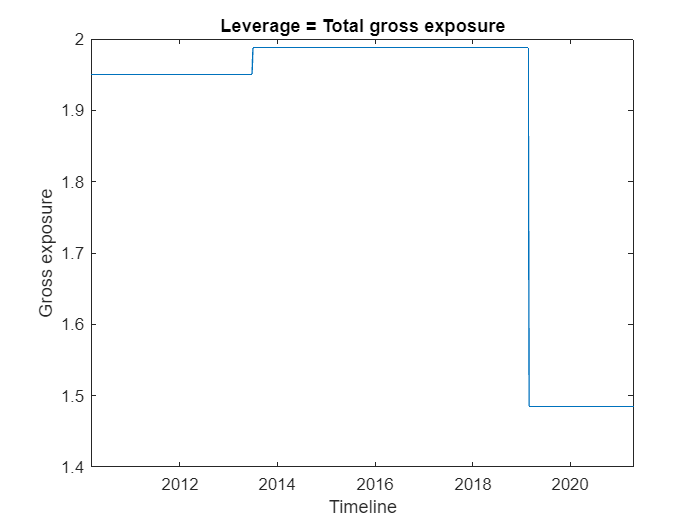

figure
plot(Date(start_index+window_used+1:end),grossExposure_lev2+1); % add 1 for your collateral + margins
title('Leverage = Total gross exposure')
xlabel('Timeline')
ylabel('Gross exposure')
hold off; 

Plot of the evolution in time of the weights of our replica portfolio

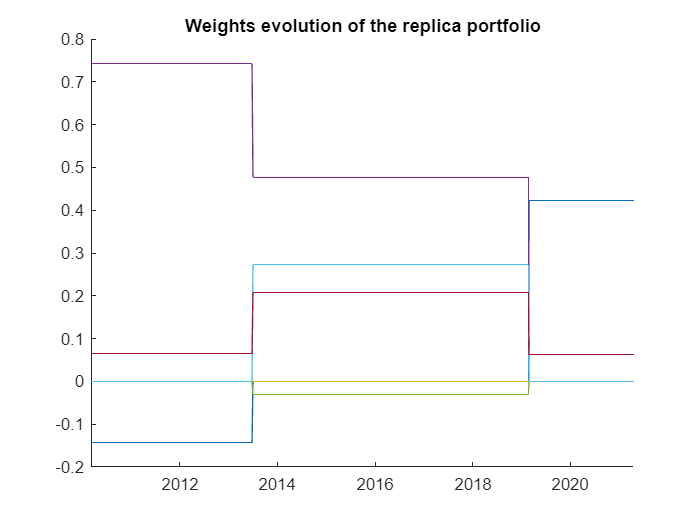

figure
hold on
for i = 1:size(weights_lev2,2)
    plot(Date(start_index+window_used+1:end),weights_lev2(:,i))
end
title('Weights evolution of the replica portfolio')

Barplot of the average weight of the assets during the whole timespan

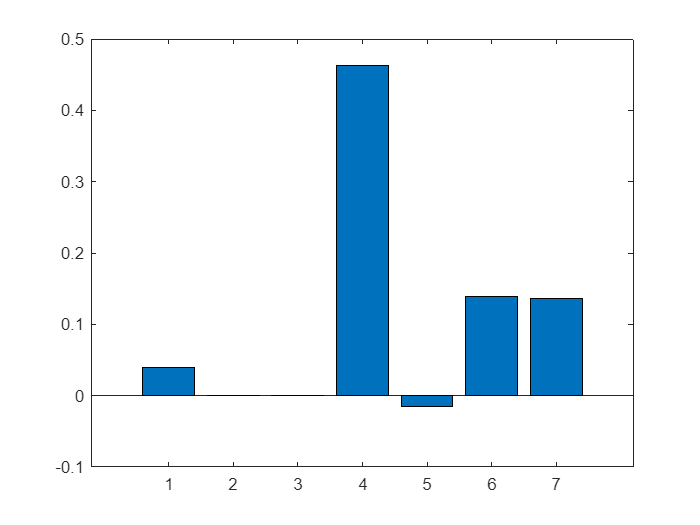

mean_weights = mean(weights_lev2,1);
figure
bar(mean_weights)

Evolution of the Weights Year by Year for Replica Portfolio

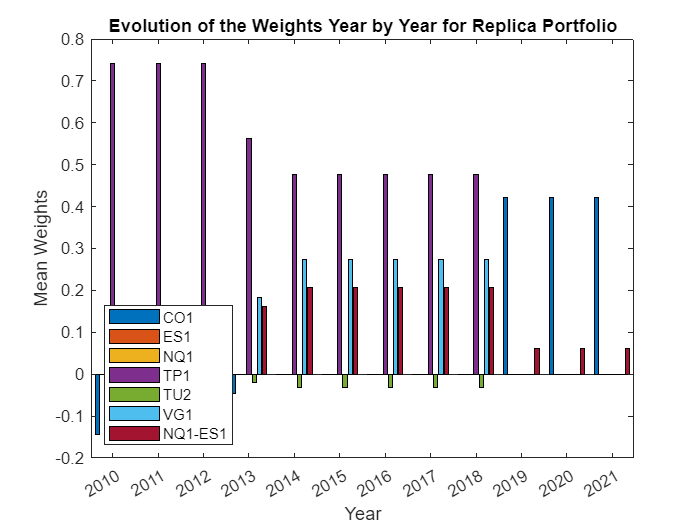

% Evaluate number of full years in our timespan
amount_years = floor(size(weights_lev2,1)/52);
mean_weights_yearly = []; % prepare vector

for i = 1:amount_years
    % save the mean annual weights for each asset, year by year
    mean_weights_yearly(:,i) = mean(weights_lev2((i-1)*52+1:i*52,:),1);
end
% Save the mean annual weights for the final dates
mean_weights_yearly(:,i+1) = mean(weights_lev2(i*52+1:end,:),1);

% Prepare variables needed for the barplots
years = 2010:(2010 + amount_years);
asset_labels = {'CO1', 'ES1', 'NQ1', 'TP1', 'TU2', 'VG1', 'NQ1-ES1'};

% Barplot of the average weight of the assets during the whole timespan
figure
bar(mean_weights_yearly')
title('Evolution of the Weights Year by Year for Replica Portfolio')
xlabel('Year')
ylabel('Mean Weights')
xticks(1:length(years))  % set the ticks on the x-axis
xticklabels(years)       % set the labels of the x-axis
legend(asset_labels, 'Location', 'SouthWest')

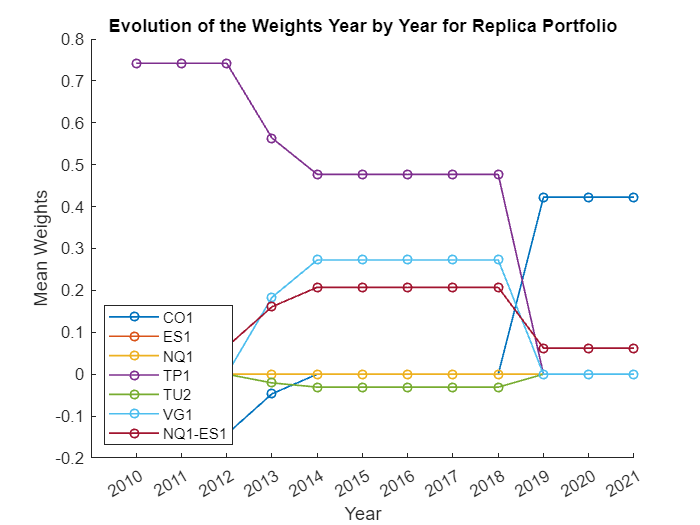

figure
hold on
for asset_idx = 1:size(mean_weights_yearly, 1)
    xx = 1:length(years);
    yy = mean_weights_yearly(asset_idx, :);
    plot(xx, yy, '-o', 'LineWidth', 1, 'MarkerSize', 5);
end
title('Evolution of the Weights Year by Year for Replica Portfolio')
xlabel('Year')
ylabel('Mean Weights')
xticks(1:length(years))  % set the ticks on the x-axis
xticklabels(years)       % set the labels of the x-axis
legend(asset_labels, 'Location', 'SouthWest')

Plot results of our investment replica model

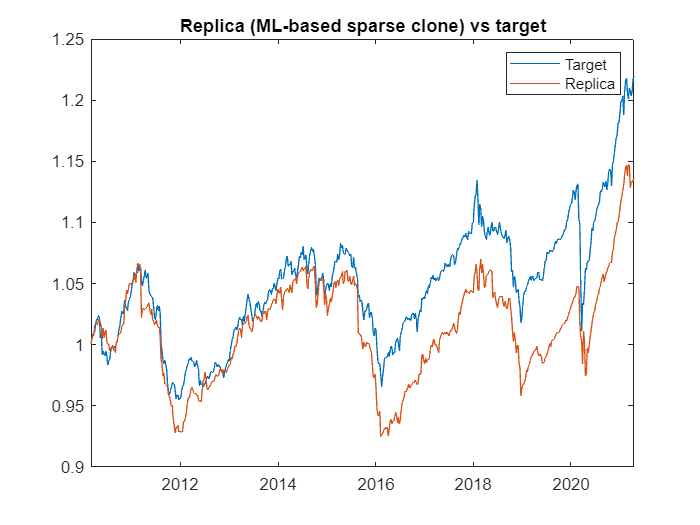

figure
plot(Date(start_index+window_used:end),ret2price(y(start_index+window_used:end)),'DisplayName','Target');
hold on;
plot(Date(start_index+window_used:end),ret2price(returns_lev2),'DisplayName','Replica');
legend
title('Replica (ML-based sparse clone) vs target')
hold off;

## Evaluate our model: Metrics

Compute Mean Squared Error (MSE) and Mean Absolute Error (MAE)

mse_lev2 = mean((ret2price(returns_lev2) - ret2price(y(start_index+window_used:end))).^2)

mse_lev2 = 0.0020

mae_lev2 = mean(abs(ret2price(returns_lev2) - ret2price(y(start_index+window_used:end))))

mae_lev2 = 0.0363

Tracking Error Volatility

TE_2 = returns_lev2 - y(start_index+window_used: end)

TE_2 =    -0.0014
    0.0004
   -0.0007
    0.0065
   -0.0055
   -0.0032
   -0.0004
    0.0014
    0.0015
    0.0135


TEV_2 = std(TE_2)*sqrt(52) % annualized

TEV_2 = 0.0463

Log-returns of the clone and the target

logRClone_2 = diff(log(ret2price(returns_lev2))); 
logRTarget_2 = diff(log(ret2price(y(start_index+window_used: end))));

logTE_2 =  logRClone_2 - logRTarget_2;  % log-returns tracking error

Mean yearly total returns of target and clone

meanTRTarget_2 = exp(mean(logRTarget_2)*52) - 1

meanTRTarget_2 = 0.0179

meanTRClone_2 = exp(mean(logRClone_2)*52) - 1

meanTRClone_2 = 0.0115

Mean excess return of the clone over the target

meanER_2 = exp(mean(logTE_2)*52) - 1

meanER_2 = -0.0063

Information Ratio: mean excess return over the tracking error volatility - similar idea to Sharpe Ratio

IR_2 = meanER_2/TEV_2

IR_2 = -0.1365

Weekly turnovers of each asset in our portfolio 

[Turnover_2] = our_calcTurnover(weights_lev2);

Mean annual turnover (since we're computing every metric as annual)

meanTurnover_2 = sum(mean(Turnover_2)*52)

meanTurnover_2 = 0.1974

Mean trading costs (percentage)

tradingCosts = 4e-4;      % transaction costs (hp: buyCosts=sellCost) 4 bps
meanTradingCosts_2 = meanTurnover_2*tradingCosts

meanTradingCosts_2 = 7.8964e-05

Net Total returns of the clone - accounting for transactions costs

NetTR_2 = meanTRClone_2 - meanTradingCosts_2 

NetTR_2 = 0.0114

Net Excess returns of the clone - accounting for transactions costs

NetER_2 = meanER_2 - meanTradingCosts_2 

NetER_2 = -0.0064

Net Information Ratio - accounting for transactions costs

NetIR_2 = NetER_2/TEV_2

NetIR_2 = -0.1382

## Kalman Filter

We implemented a Kalman Filter, an algorithm that makes a "Digital twin" of the system and tries to follow it with a feedback correction on the output error utilizing the gain. There are many advantages in using this algorithm: computational efficiency, the ability to separate true data from noise and its capability to dinamically adjust to new data which is a key feature when analyzing financial data due to the unpredictability of markets.

X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];

prices = X;
index = y;

n_times = 704;
n_assets = 11;

% our initial guess are the weights that minimize the MAE (Minimum Absolute Error) 
% of the first week in our data
L = @(xx) mean(abs(index - prices(1,:)*xx));
w = fmincon(@(x) L(x),ones(n_assets,1)/n_assets,[],[]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Our state space representation of the Kalman Filter is:

X(t) = A*X(t-1) + Q*v(t)

Y(t) = C*X(t) + R*w(t)

where :

- X(t) is the vector of the weights

- Y(t) is the value of the index we are replicating

-  A is the identity matrix

- Q is a diagonal matrix

- C is the matrix of the weights

- R is the observation noise

- both v(t) and w(t) are normally distributed and are independent

P = cov(X); 
R = 0.1; 
% grid for the values of the hyperparameter Q
l = linspace(1,50,50);
% initialization of the evaluation metrics
TEV = zeros(50,1);
mean_GE = zeros(50,1);

for i = 1:50
    % process noise
    Q = l(i)*eye(n_assets); 
    % initialization
    GrossExposure = [];
    b = [];
    returns = [];
for t=1:n_times
    w_pred=w;
    P_pred = P+Q;
    x_t = prices(t,:)';
    % Kalman Gain
    K = P_pred*x_t/(x_t'*P_pred*x_t + R);
    y_t = index(t);         

Weights update is given by the equation:

w(t + 1 | t) = A*w(t | t-1) + K(t)*e(t)

where e(t) is the error given i.e. e(t) = y(t) - C*w(t | t-1)

    w = w_pred + K*(y_t - x_t'*w_pred); 
    P = (eye(n_assets) - K*x_t')*P_pred;

    GrossExposure = [GrossExposure; sum(abs(w))];
    b = [b; w'];
    r = X(t,:)*w;
    returns = [returns; r];

end
TE = returns - y;
TEV(i) = std(TE)*sqrt(52);
mean_GE(i) = mean(GrossExposure);
end

We decided to implement for the hyperparameters tuning a measure that is given by the sum of the Tracking Error Volatility and the mean of the Gross Exposure both scaled using the min-max scaling technique this to grant a avoid overfitting that could lead to a high Gross Exposure and a high cost for Trading

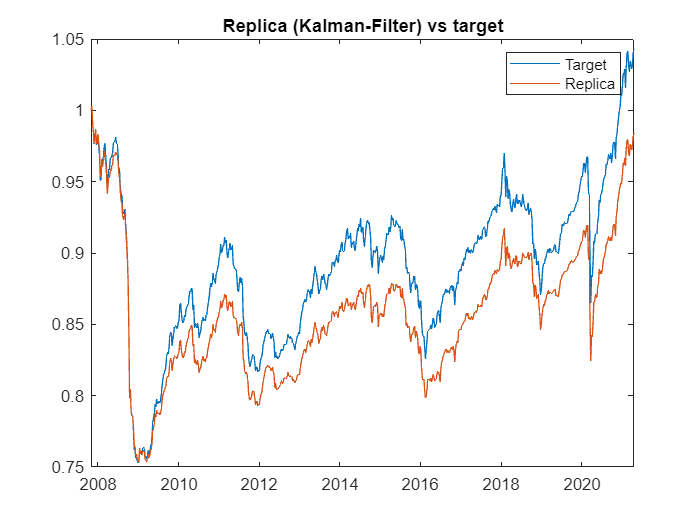

TEV_GE = (TEV - min(TEV))/(max(TEV) - min(TEV)) + ...
    (mean_GE - min(mean_GE))/(max(mean_GE) - min(mean_GE));

idx = find(min(TEV_GE) == TEV_GE);
w = ones(n_assets,1)/n_assets;
Q = l(idx)*eye(n_assets);


GrossExposure = [];
b = [];
returns = [];

We finish computing our Kalman Filter using the value that minimizes our new metric which is Q = 15*Id

for t=1:n_times

mse_lev2 = 0.0013

mae_lev2 = 0.0329

    w_pred=w;
    P_pred = P+Q;
    x_t = prices(t,:)';

TEV = 0.0105

    K = P_pred*x_t/(x_t'*P_pred*x_t + R); % Kalman Gain

    y_t = index(t);
    wnew=w_pred + K*(y_t - x_t'*w_pred);
    w = w_pred + K*(y_t - x_t'*w_pred); % Aggiornamento pesi
    P = (eye(n_assets) - K*x_t')*P_pred;

meanTRTarget = 0.0038

meanTRClone = -4.9500e-04

    GrossExposure = [GrossExposure; sum(abs(w))];
    b = [b; w'];

meanER = -0.0043

    r = X(t,:)*w;
    returns = [returns; r];

IR = -0.4124


end

## Plot

Plot results of our investment replica model

figure

meanTurnover =     1.1280    1.1951    1.1124    1.1431    0.3704    1.1055    1.1266    1.1084    1.2010    1.0980    1.1479


plot(Date(2:end),ret2price(y(2:end)),'DisplayName','Target');
hold on;
plot(Date(2:end),ret2price(returns(2:end)),'DisplayName','Replica');

meanTradingCosts = 1.0e-03 *

    0.9024    0.9561    0.8899    0.9144    0.2963    0.8844    0.9013    0.8867    0.9608    0.8784    0.9183


legend
title('Replica (Kalman-Filter) vs target')

NetTR =    -0.0014   -0.0015   -0.0014   -0.0014   -0.0008   -0.0014   -0.0014   -0.0014   -0.0015   -0.0014   -0.0014


hold off;

## Evaluate our model: Metrics

Compute Mean Squared Error (MSE) and Mean Absolute Error (MAE)

mse_lev2 = mean((ret2price(returns) - ret2price(y)).^2)

NetER =    -0.0052   -0.0053   -0.0052   -0.0052   -0.0046   -0.0052   -0.0052   -0.0052   -0.0053   -0.0052   -0.0052


mae_lev2 = mean(abs(ret2price(returns) - ret2price(y)))

Tracking Error Volatility

TE = returns - y; % tracking error

NetIR =    -0.4987   -0.5038   -0.4975   -0.4999   -0.4408   -0.4970   -0.4986   -0.4972   -0.5043   -0.4964   -0.5002


TEV = std(TE)*sqrt(52)

Log-returns of the clone and the target

logRClone = diff(log(ret2price(returns))); % ...much easier to compute annualized metrics from log-returns
logRTarget = diff(log(ret2price(y)));
logTE =  logRClone - logRTarget;

Log-returns of the clone and the target

meanTRTarget = exp(mean(logRTarget)*52) - 1
meanTRClone = exp(mean(logRClone)*52) - 1

Mean excess return of the clone over the target

meanER = exp(mean(logTE)*52) - 1

Information Ratio: mean excess return over the tracking error volatility - similar idea to Sharpe Ratio

IR = meanER/TEV

Weekly turnovers of each asset in our portfolio 

Turnover = our_calcTurnover(b);

Mean annual turnover (since we're computing every metric as annual)

meanTurnover = mean(Turnover)*52 % mean annual turnover (since we're computing every metric as annual)

Mean trading costs (percentage)

tradingCosts = 0.0008; % transaction costs (hp: buyCosts=sellCost)
meanTradingCosts = meanTurnover*tradingCosts

Net Total returns of the clone - accounting for transactions costs

NetTR = meanTRClone - meanTradingCosts % transaction costs (hp: buyCosts=sellCost)

Net Excess returns of the clone - accounting for transactions costs

NetER = meanER - meanTradingCosts % check in the end the returns compared with the trading costs

Net Information Ratio - accounting for transactions costs

NetIR = NetER/TEV